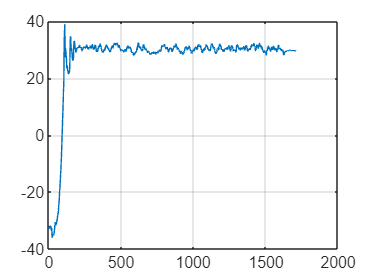

% data import
m1_train = importdata('m1_data.csv');
m2_train = importdata('m2_data.csv');
x_train_m1 = m1_train(:,1);
y_train_m1 = m1_train(:,2);
x_train_m2 = m2_train(:,1);
y_train_m2 = m2_train(:,2);

%data plot
plot(y_train_m1);
grid on

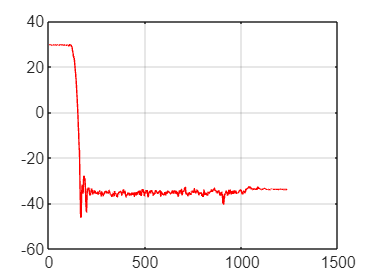

plot(y_train_m2, 'r');
grid on


te = 0.01; %Perioada de esantionare
fs = 1/te; %Frecventa
fc = 5/6 %Frecventa de taiere

fc = 0.8333

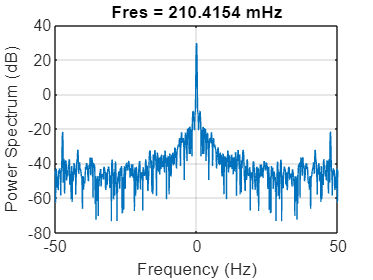


%spectrul de frecvente
pspectrum(y_train_m1,fs,'Leakage',0,'TwoSided',true)

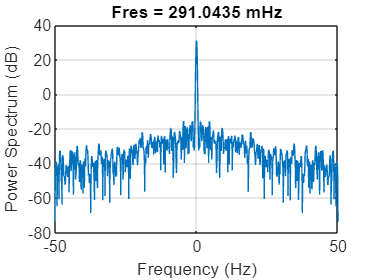

pspectrum(y_train_m2,fs,'Leakage',0,'TwoSided',true)

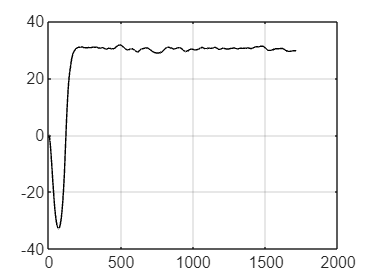


%butterworth filter
[b, a] = butter(2, fc/(fs/2),'low'); % coeficentii filtrului
m1_filtrat = filter(b, a, y_train_m1); %filtrarea motor 1
m2_filtrat = filter(b, a, y_train_m2); %filtrarea motor 2

%filtered data
plot(m1_filtrat, 'k');
grid on

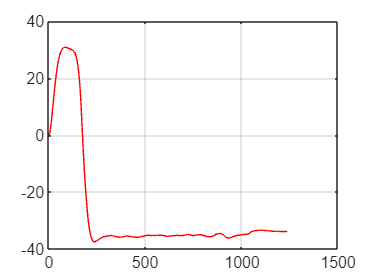

plot(m2_filtrat, 'r');
grid on


% plot(out_b_lp_copy,'r') %Pentru lowpass plot(filtru,'r')

G1 =
 
                                                                     
                                                3.184e04 s + 2.107e04
                                                                     
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  s^9 + 16.79 s^8 + 267.3 s^7 + 2473 s^6 + 1.767e04 s^5 + 8.79e04 s^4 + 3.081e05 s^3 + 7.278e05 s^2 + 1.04e06 s     
                                                                                                                    
                                                                                                           + 7.52e05
                                                                                                                    
 
Continuous-time transfer function.



Reg1 =
 
  1.707e-06 s + 0.003414
  ----------------------
         0.0005 s
 
Continuous-time transfer function.



Gd1 =
 
                                                                         
                                            0.05435 s^2 + 108.7 s + 71.95
                                                                         
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  0.0005 s^10 + 0.008395 s^9 + 0.1337 s^8 + 1.236 s^7 + 8.833 s^6 + 43.95 s^5 + 154 s^4 + 363.9 s^3 + 519.9 s^2     
                                                                                                                    
                                                                                                             + 376 s
                                                                                                                    
 
Continuous-time transfer function.



G01 =
 
                                                                         
                                            0.05435 s^2 + 108.7 s + 71.95
                                                                         
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  0.0005 s^10 + 0.008395 s^9 + 0.1337 s^8 + 1.236 s^7 + 8.833 s^6 + 43.95 s^5 + 154 s^4 + 363.9 s^3 + 519.9 s^2     
                                                                                                                    
                                                                                                   + 484.7 s + 71.95
                                                                                                                    
 
Continuous-time transfer function.



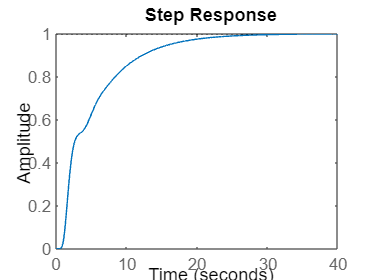

ans = struct with fields:
         RiseTime: 10.9889
    TransientTime: 21.2324
     SettlingTime: 21.2324
      SettlingMin: 0.9001
      SettlingMax: 0.9995
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9995
         PeakTime: 41.7782


s = tf('s');

%regulator M1
Kp1 = PID_M1.Kp;
Ti1 = PID_M1.Ti;
G1 = tf(TF_M1.Numerator, TF_M1.Denominator)
Reg1 = Kp1*(1+  (1/(s*Ti1)))
Gd1 = series(Reg1,G1)
G01 = feedback(Gd1,1)
step(G01)
stepinfo(G01)

%regulator M2
Kp2 = PID_M2.Kp;
Ti2 = PID_M2.Ti;

G2 = tf(TF_M2.Numerator, TF_M2.Denominator)

G2 =
 
                                                                    
                                                 -923.9 s - 1.127e04
                                                                    
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  s^10 + 31.45 s^9 + 300.2 s^8 + 2731 s^7 + 1.46e04 s^6 + 6.547e04 s^5 + 2.043e05 s^4 + 4.778e05 s^3 + 7.823e05 s^2 
                                                                                                                    
                                                                                             + 7.819e05 s + 3.496e05
                                                                                                                    
 
Continuous-time transfer function.



Reg2 = Kp2*(1+  (1/(s*Ti2)))

Reg2 =
 
  -29.99 s - 13.07
  ----------------
      2.294 s
 
Continuous-time transfer function.



Gd2 = series(Reg2,G2)

Gd2 =
 
                                                                            
                                          2.771e04 s^2 + 3.5e05 s + 1.473e05
                                                                            
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  2.294 s^11 + 72.14 s^10 + 688.8 s^9 + 6266 s^8 + 3.349e04 s^7 + 1.502e05 s^6 + 4.686e05 s^5 + 1.096e06 s^4        
                                                                                                                    
                                                                          + 1.795e06 s^3 + 1.794e06 s^2 + 8.021e05 s
                                                                                                                    
 
Continuous-time transfer function.



G02 = feedback(Gd2,1)

G02 =
 
                                                                            
                                          2.771e04 s^2 + 3.5e05 s + 1.473e05
                                                                            
  ------------------------------------------------------------------------------------------------------------------
                                                                                                                    
  2.294 s^11 + 72.14 s^10 + 688.8 s^9 + 6266 s^8 + 3.349e04 s^7 + 1.502e05 s^6 + 4.686e05 s^5 + 1.096e06 s^4        
                                                                                                                    
                                                               + 1.795e06 s^3 + 1.821e06 s^2 + 1.152e06 s + 1.473e05
                                                                                                                    
 
Continuous-time transfer function.



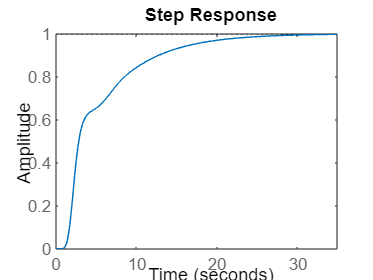

step(G02)

stepinfo(G02)

ans = struct with fields:
         RiseTime: 11.0993
    TransientTime: 22.5275
     SettlingTime: 22.5275
      SettlingMin: 0.9007
      SettlingMax: 0.9979
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9979
         PeakTime: 36.2068


%discretizare
Regz1 = c2d(Reg1,te,'foh')

Regz1 =
 
  0.03756 z + 0.03073
  -------------------
         z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Regz2 = c2d(Reg2,te,'foh')

Regz2 =
 
  -13.1 z + 13.04
  ---------------
       z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Regz1.Variable = 'z^-1'

Regz1 =
 
  0.03756 + 0.03073 z^-1
  ----------------------
         1 - z^-1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Regz2.Variable = 'z^-1'

Regz2 =
 
  -13.1 + 13.04 z^-1
  ------------------
       1 - z^-1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



[uzd1, yzd1] = tfdata(Regz1, 'v')

uzd1 =    0.037556772508577   0.030728268395416


yzd1 =      1    -1


[uzd2, yzd2] = tfdata(Regz2, 'v')

uzd2 =  -13.100701652605988  13.043720316359739


yzd2 =      1    -1
